##                                                      Robótica - Lista de Exercícios 3

**                        Nome: **Marcos Carvalho Ferreira                                                                            **Matrícula:** 202010203

import RoboticaBiblioteca.*
printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


**Questão 1**

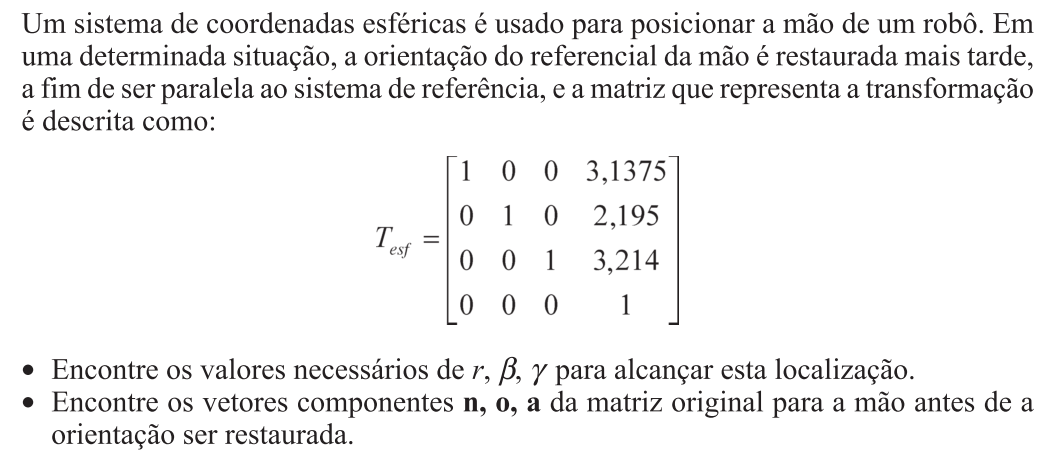

**a)**

[r, beta, gama] = movimentosTesf(3.1375,2.195,3.214);

r = 4.999173 | beta = 49.991116 | gamma = 34.976697


**b) **

Tesf(r,beta,gama)

ans =     0.5268   -0.5732    0.6276    3.1375
    0.3685    0.8194    0.4391    2.1950
   -0.7659         0    0.6429    3.2140
         0         0         0    1.0000


**Questão 2**

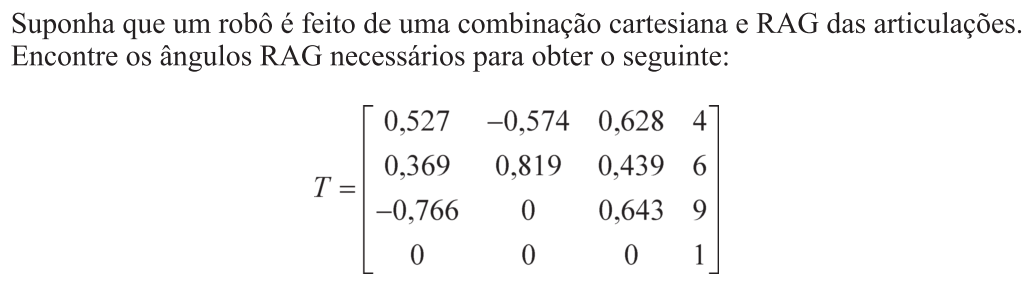

[Px, Py, Pz] = movimentosTcart(4,6,9);

Px = 4.000000 | Py = 6.000000 | Pz = 9.000000


[ThetaN, ThetaO, ThetaA] = angsRAG([0.527 -0.574 0.628 4;
                                    0.369 0.819 0.439 6;
                                    -0.766 0 0.643 9;
                                    0 0 0 1]);

ThetaN = 0.033750 | ThetaO = 49.974002 | ThetaA = 34.999316


rotRAG(ThetaN,ThetaO,ThetaA)

ans =     0.6431    0.4387    0.6276         0
    0.0004    0.8194   -0.5732         0
   -0.7658    0.3689    0.5268         0
         0         0         0    1.0000


syms phi theta psi;
rotRAG(phi, theta, psi)

$$ans = \left(\begin{array}{cccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & 0\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Questão 3**

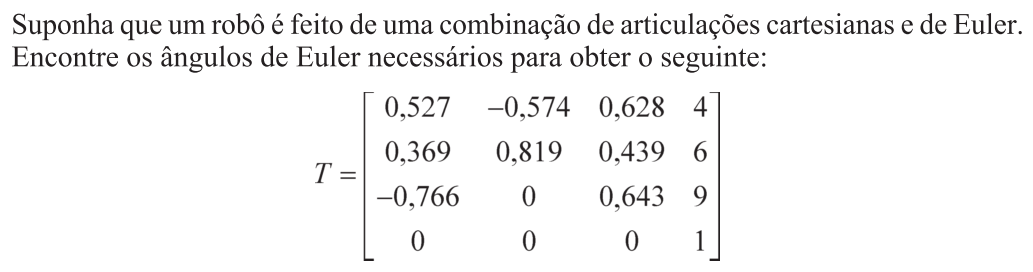

[Px, Py, Pz] = movimentosTcart(4,6,9);

Px = 4.000000 | Py = 6.000000 | Pz = 9.000000


[Phi, Theta, Psi] = angsEuler([0.527 -0.574 0.628 4;
                               0.369 0.819 0.439 6;
                              -0.766 0 0.643 9;
                               0 0 0 1]);

phi = 34.955265 | theta = 49.984113 | psi = 0.000000


rotZYZ(Phi, Theta, Psi)

ans =     0.5270   -0.5729    0.6277         0
    0.3684    0.8196    0.4388         0
   -0.7659         0    0.6430         0
         0         0         0    1.0000


**Questão 4**

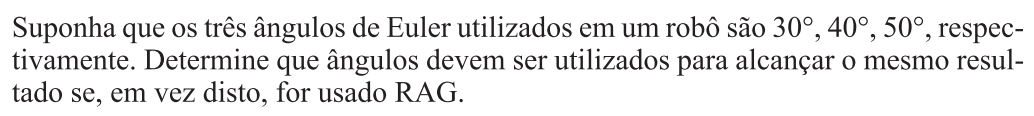

Matriz = rotZYZ(30,40,50)

Matriz =     0.0434   -0.8296    0.5567         0
    0.9096    0.2633    0.3214         0
   -0.4132    0.4924    0.7660         0
         0         0         0    1.0000


[ThetaN, ThetaO, ThetaA] = angsRAG(Matriz);

ThetaN = 32.732407 | ThetaO = 24.404497 | ThetaA = 87.267593


confusao()

phi = thetaA
theta = thetaO
psi = thetaN


rotRAG(ThetaA, ThetaO, ThetaN)

ans =     0.0434   -0.8296    0.5567         0
    0.9096    0.2633    0.3214         0
   -0.4132    0.4924    0.7660         0
         0         0         0    1.0000


**Questão 5**

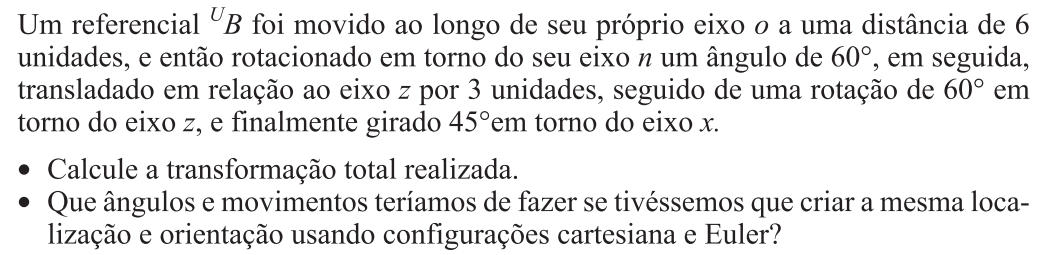

B = trans(0,0,0)

B =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


B = rot('x',45)*rot('z',60)*trans(0,0,3)*B*trans(0,6,0)*rot('n',60)

B =     0.5000   -0.4330    0.7500   -5.1962
    0.6124   -0.4356   -0.6597         0
    0.6124    0.7891    0.0474    4.2426
         0         0         0    1.0000


[Px, Py, Pz] = movimentosTcart(-5.1962,0,4.2426);

Px = -5.196200 | Py = 0.000000 | Pz = 4.242600


[Phi, Theta, Psi] = angsEuler(B);

phi = -41.336564 | theta = 87.285045 | psi = 127.811133


Tcart(Px, Py, Pz)*rotZYZ(Phi,Theta,Psi)

ans =     0.5000   -0.4330    0.7500   -5.1962
    0.6124   -0.4356   -0.6597         0
    0.6124    0.7891    0.0474    4.2426
         0         0         0    1.0000
